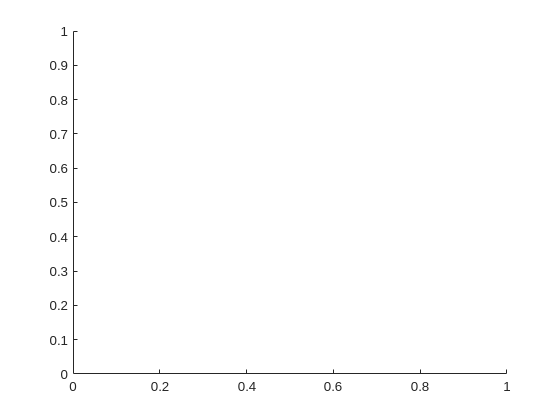

Unrecognized function or variable 't'.

Error in task>label (line 39)
plot(t, f0 / 1000, 'r.');

[x, fs] = audioread("aeiouy.wav");
x = x / max(x);

lbls = label(x, fs);



f0 = pitchwin(x, fs, round(fs * 0.1));
f0(lbls ~= 2) = 0;

silence = x;
silence(lbls ~= 0) = 0;

unvoiced = x;
unvoiced(lbls ~= 1) = 0;

voiced = x;
voiced(lbls ~= 2) = 0;

figure;
hold on;
plot(unvoiced);
plot(voiced);
plot(silence);
ylim([-1, 1]);
legend("unvoiced", "voiced", "silence");

figure;
t = linspace(0, length(x)/fs, length(x));

plot(f0);
spectrogram(x, win, win/2, [], fs, 'yaxis');
hold on;
plot(t, f0 / 1000, 'r.');
hold on;
plot(t, f0*10/1000, 'g.');

function lbls = label(x, fs)
% długość okna analizy: 200 msspectrogram(x, win, win/2, [], fs, 'yaxis');
hold on;
plot(t, f0 / 1000, 'r.');
win = round(fs * 0.2);
lbls = zeros(length(x), 1);
% energia chwilowa
ste = conv(x.^2, ones(1,win), 'same');
ste = ste / max(ste);

% wersja z pierwiastkiem
str = sqrt(ste);

lbls = double(str > 0.05);

x1 = x;
x2 = [0; x(1:end-1)];
diff = sign(x1) ~= sign(x2);

zcr = conv(diff, ones(1, win) / win, "same");

for i=1:length(lbls)
   if(lbls(i))
        b = zcr(i) > 0.3;
        lbls(i) = lbls(i) + ~b;
   end
end

end 


function f0 = pitchwin(x, fs, win_len)
    f0 = zeros(length(x),1);
    for i =1:floor(length(x)/win_len)
        
        window = x(1+(i-1)*win_len:i*win_len);
    
    f_max = 300;
    lag_min = fs / f_max;
    [c, lags] = xcorr(window, 'normalized');
    c = c(lags > lag_min);
    lags = lags(lags > lag_min);
    [pks, loc] = findpeaks(c, "MinPeakProminence", 0.2, "MinPeakWidth", 3);
    
    [~, I] = max(pks);
    lag_s = fs / loc(I);
    % disp(lag_s)
    if(length(lag_s) == 0)
        f0(1+(i-1)*win_len:i*win_len) = ones(length(f0(1+(i-1)*win_len:i*win_len)),1) * 0;

    else
        f0(1+(i-1)*win_len:i*win_len) = ones(length(f0(1+(i-1)*win_len:i*win_len)),1)*lag_s;
    end

    end
end

function zcr = zerocrossrate(x)
    x1 = x;
    x2 = [0; x(1:end-1)];
    diff = sign(x1) ~= sign(x2);
    
    zcr = conv(diff, ones(1, win) / win, "same");
end